clear; clc; close all;

%% user input


% plane loudness
fprintf('Sound Power Level (L_W)\n');

Sound Power Level (L_W)


fprintf('  Small turboprop  ~135 dB\n');

  Small turboprop  ~135 dB


fprintf('  Narrow-body jet  ~155 dB\n');

  Narrow-body jet  ~155 dB


fprintf('  Heavy widebody   ~165 dB\n');

  Heavy widebody   ~165 dB


L_W = input('  Enter L_W [dB] (e.g. 155): ');
while ~isnumeric(L_W) || ~isscalar(L_W) || L_W < 100 || L_W > 200
    fprintf('  Invalid. Enter a value between 100 and 200.\n');
    L_W = input('  Enter L_W [dB]: ');
end

% aircraft altitude 
fprintf('\nAltitude\n');


Altitude


fprintf('  Landing approach  ~300 m\n');

  Landing approach  ~300 m


fprintf('  Low overflight    ~600 m\n');

  Low overflight    ~600 m


fprintf('  High overflight   ~3000 m\n');

  High overflight   ~3000 m


h = input('  Enter altitude [m] (e.g. 500): ');
while ~isnumeric(h) || ~isscalar(h) || h <= 0 || h > 15000
    fprintf('  Invalid. Enter a positive value up to 15000 m.\n');
    h = input('  Enter altitude [m]: ');
end

% aircraft speed 
fprintf('\nGround Speed\n');


Ground Speed


fprintf('  Final approach  ~70 m/s  (~250 km/h)\n');

  Final approach  ~70 m/s  (~250 km/h)


fprintf('  Departure       ~100 m/s (~360 km/h)\n');

  Departure       ~100 m/s (~360 km/h)


fprintf('  Cruise overflight ~250 m/s\n');

  Cruise overflight ~250 m/s


v = input('  Enter speed [m/s] (e.g. 100): ');
while ~isnumeric(v) || ~isscalar(v) || v <= 0 || v > 400
    fprintf('  Invalid. Enter a value between 0 and 400 m/s.\n');
    v = input('  Enter speed [m/s]: ');
end

% atmospheric absorption 
fprintf('\nAtmosperic Absorption (alpha)\n');


Atmosperic Absorption (alpha)


fprintf('  Typical dry air at 1 kHz  ~0.002 dB/m\n');

  Typical dry air at 1 kHz  ~0.002 dB/m


fprintf('  Humid air                 ~0.001 dB/m\n');

  Humid air                 ~0.001 dB/m


fprintf('  High frequency (4 kHz)    ~0.008 dB/m\n');

  High frequency (4 kHz)    ~0.008 dB/m


alpha = input('  Enter alpha [dB/m] (e.g. 0.002): ');
while ~isnumeric(alpha) || ~isscalar(alpha) || alpha < 0 || alpha > 0.1
    fprintf('  Invalid. Enter a value between 0 and 0.1.\n');
    alpha = input('  Enter alpha [dB/m]: ');
end



%% model setup

dt    = 0.5;          % timestep [s]
x_end = 5000;         % stop when aircraft reaches +5000 m [m]
x = -5000;            % initial horizontal position [m]
t = 0;                % initial time [s]

% Storage
t_hist  = [];
dB_hist = [];
x_hist  = [];

%%

while x <= x_end

    % Slant range from aircraft to receiver on ground
    %   r = sqrt(x^2 + h^2)
    r = sqrt(x^2 + h^2);

    % Point-source propagation equation
    %   L(r) = L_W - 20*log10(r) - 11 - alpha*r
    dB = L_W - 20*log10(r) - 11 - alpha*r;

    % Clamp to zero (model does not go negative)
    dB = max(dB, 0);

    % Store values
    t_hist(end+1)  = t;  
    dB_hist(end+1) = dB; 
    x_hist(end+1)  = x;  

    % Advance aircraft position and time
    x = x + v * dt;
    t = t + dt;
end

%% peak noise

[peak_dB, idx_peak] = max(dB_hist);
t_peak = t_hist(idx_peak);
x_peak = x_hist(idx_peak);

fprintf('Simulation complete.\n');

Simulation complete.


fprintf('  Peak noise level : %.1f dB\n', peak_dB);

  Peak noise level : 89.0 dB


fprintf('  Time of peak     : %.1f s\n',  t_peak);

  Time of peak     : 71.5 s


fprintf('  Aircraft position at peak: %.0f m\n', x_peak);

  Aircraft position at peak: 5 m


fprintf('  (closest approach at x = 0, i.e. directly overhead)\n\n');

  (closest approach at x = 0, i.e. directly overhead)



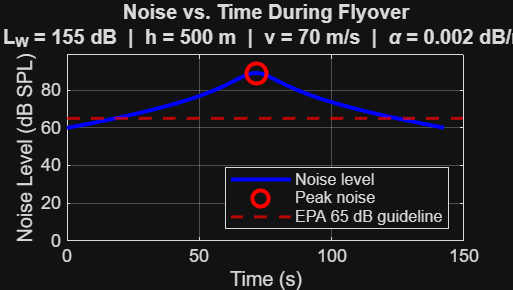


%% noise vs. time graph

figure('Name','Noise vs. Time','NumberTitle','off', ...
       'Position',[100 100 800 450]);

plot(t_hist, dB_hist, 'b-', 'LineWidth', 2);
hold on;
plot(t_peak, peak_dB, 'ro', 'MarkerSize', 10, 'LineWidth', 2, ...
     'DisplayName', sprintf('Peak: %.1f dB at t = %.1f s', peak_dB, t_peak));
yline(65, 'r--', 'LineWidth', 1.5, 'DisplayName', 'EPA guideline (65 dB)');

xlabel('Time (s)');
ylabel('Noise Level (dB SPL)');
title(sprintf('Noise vs. Time During Flyover\nL_W = %d dB  |  h = %d m  |  v = %d m/s  |  \\alpha = %.3f dB/m', ...
      L_W, h, v, alpha));
legend('Noise level','Peak noise','EPA 65 dB guideline','Location','southeast');
grid on;
ylim([0, max(dB_hist) + 10]);

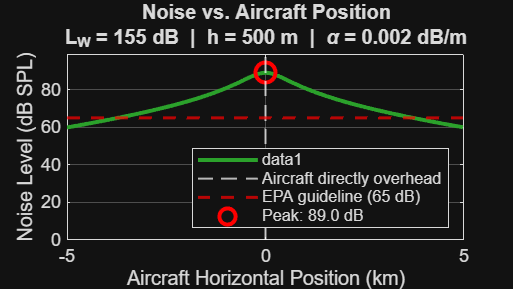


%% noise vs distance graph

figure('Name','Noise vs. Distance','NumberTitle','off', ...
       'Position',[100 600 800 450]);

plot(x_hist/1000, dB_hist, 'Color', [0.17 0.63 0.17], 'LineWidth', 2);
hold on;
xline(0, 'w--', 'LineWidth', 1, 'DisplayName', 'Aircraft directly overhead');
yline(65, 'r--', 'LineWidth', 1.5, 'DisplayName', 'EPA guideline (65 dB)');
plot(x_peak/1000, peak_dB, 'ro', 'MarkerSize', 10, 'LineWidth', 2, ...
     'DisplayName', sprintf('Peak: %.1f dB', peak_dB));

xlabel('Aircraft Horizontal Position (km)');
ylabel('Noise Level (dB SPL)');
title(sprintf('Noise vs. Aircraft Position\nL_W = %d dB  |  h = %d m  |  \\alpha = %.3f dB/m', ...
      L_W, h, alpha));
legend('Location','southeast');
grid on;
ylim([0, max(dB_hist) + 10]);

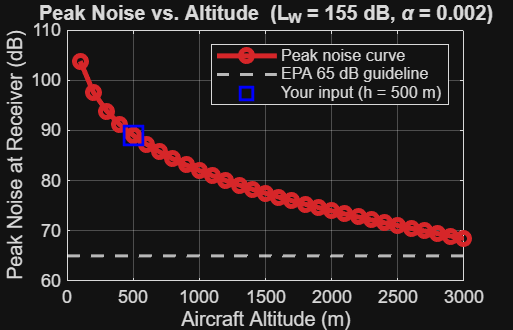


%% peak noise vs. altitude
%    (Fixed L_W and alpha; sweep altitude)

alt_range    = 100:100:3000;              % altitudes to test [m]
peak_vs_alt  = zeros(size(alt_range));

for k = 1:length(alt_range)
    h_k   = alt_range(k);
    x_k   = -5000;
    dB_max = 0;
    while x_k <= x_end
        r_k     = sqrt(x_k^2 + h_k^2);
        dB_k    = L_W - 20*log10(r_k) - 11 - alpha*r_k;
        dB_max  = max(dB_max, dB_k);
        x_k     = x_k + v*dt;
    end
    peak_vs_alt(k) = dB_max;
end

figure('Name','Sensitivity: Altitude','NumberTitle','off', ...
       'Position',[950 100 700 450]);

plot(alt_range, peak_vs_alt, 'o-', 'LineWidth', 2.5, 'MarkerSize', 6, ...
     'Color', [0.84 0.15 0.16]);
hold on;
yline(65, 'w--', 'LineWidth', 1.5, 'DisplayName', 'EPA guideline (65 dB)');
plot(h, peak_dB, 'bs', 'MarkerSize', 12, 'LineWidth', 2, ...
     'DisplayName', sprintf('Your input: h = %d m', h));

xlabel('Aircraft Altitude (m)');
ylabel('Peak Noise at Receiver (dB)');
title(sprintf('Peak Noise vs. Altitude  (L_W = %d dB, \\alpha = %.3f)', L_W, alpha));
legend('Peak noise curve','EPA 65 dB guideline', ...
       sprintf('Your input (h = %d m)', h), 'Location','northeast');
grid on;


%% data


fprintf('  Airport Noise Simulation - Summary\n');

  Airport Noise Simulation - Summary


fprintf('  L_W = %d dB  |  h = %d m  |  v = %d m/s  |  alpha = %.3f dB/m\n', ...
        L_W, h, v, alpha);

  L_W = 155 dB  |  h = 500 m  |  v = 70 m/s  |  alpha = 0.002 dB/m



fprintf('  Time (s)  |  x (m)    |  Noise (dB)\n');

  Time (s)  |  x (m)    |  Noise (dB)




% Print every ~10th row to keep output manageable
step = max(1, floor(length(t_hist)/15));
for i = 1:step:length(t_hist)
    fprintf('  %7.1f  |  %7.0f  |  %7.1f\n', ...
            t_hist(i), x_hist(i), dB_hist(i));
end

      0.0  |    -5000  |     59.9
      9.5  |    -4335  |     62.5
     19.0  |    -3670  |     65.2
     28.5  |    -3005  |     68.2
     38.0  |    -2340  |     71.6
     47.5  |    -1675  |     75.7
     57.0  |    -1010  |     80.7
     66.5  |     -345  |     87.1
     76.0  |      320  |     87.3
     85.5  |      985  |     80.9
     95.0  |     1650  |     75.8
    104.5  |     2315  |     71.8
    114.0  |     2980  |     68.4
    123.5  |     3645  |     65.3
    133.0  |     4310  |     62.6
    142.5  |     4975  |     60.0



fprintf('====================================================\n');

fprintf('  Peak: %.1f dB at t = %.1f s  (x = %.0f m)\n\n', ...
        peak_dB, t_peak, x_peak);

  Peak: 89.0 dB at t = 71.5 s  (x = 5 m)




% check for peak (occurs at x = 0, r = h)
r_peak_analytical = h;
dB_peak_analytical = L_W - 20*log10(r_peak_analytical) - 11 - alpha*r_peak_analytical;
fprintf('  Analytical peak (at x=0): %.2f dB\n', dB_peak_analytical);

  Analytical peak (at x=0): 89.02 dB


fprintf('  Simulation peak         : %.2f dB\n', peak_dB);

  Simulation peak         : 89.02 dB


fprintf('  Difference              : %.2f dB\n\n', abs(dB_peak_analytical - peak_dB));

  Difference              : 0.00 dB

